#### X.2.1 Time domain tuning

Start with some regular exercises to measure the stiffness

Kp: with increasing force it has more oscillation to go back, with slow perturbbations, the stiffness increases more and more. With fast and light perturbations it quickly shoots back to the setpoint. It always quickly gains momentum to move back.

Kd: on the other hand causes damping of fast movements in that it reduces the motion and damps the actual force that you try to apply. You don't see it returning however, that is only caused by the proportional gain that returns the system to a setpoint.

#### X.2.2 FRF measurement

% How does this actually work?
% SPERTE_Measure_And_Collect(6,2,1000,"Reference_model_Control_Engineering",1)

% Adjust parameters 
Fs = 2000;
Ts = 1/Fs;

% Adjustable parameters
res = 1.0; % in Herz
nfft = Fs / res;
noverlap = nfft/2;
% Import all signals
e_mm = simout_disturb.signals.values;
% d_mm = simout_disturb.signals.values;
% e_mm = simout_error.signals.values;
y_mm = simout_y.signals.values;

% Let's make the two-point estimate and the three point estimate
[Sens_2p, f_Sens_2p] = tfestimate(e_mm,y_mm,hann(nfft),noverlap,nfft,Fs);
f_Sens_2p = f_Sens_2p;

figure;
t1 = tiledlayout(3,1);
nexttile
semilogx(f_Sens_2p, 20*log10(abs(Sens_2p)));
title("Magnitude sensitivity closed loop FRF")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid on
nexttile 
semilogx(f_Sens_2p, angle(Sens_2p)*180/pi);
title("Phase sensitivity closed loop FRF")
xlabel("Frequency (Hz)")
ylabel("Phase")
grid on
nexttile
[coh_2p, f_coh_2p] = mscohere(e_mm, y_mm,hann(nfft),noverlap,nfft,Fs);
semilogx(f_coh_2p, coh_2p)
title("Coherence process sensitivity closed loop FRF")
xlabel("Frequency (Hz)")
ylabel("Coherence")
grid on
% Now calculate the 2-point open loop 

#### If IMAGES export

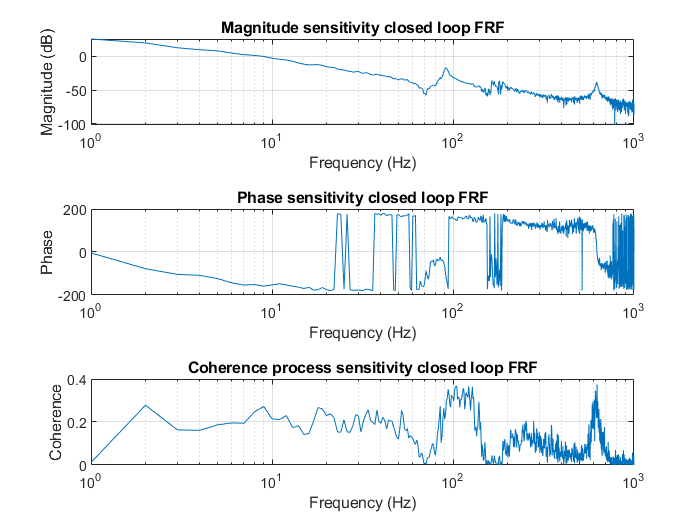

% Export all results
% exportgraphics(t1, 'Sensitivity_FRF_2pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics

% exportgraphics(t2, 'Openloop_FRF_2pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics
% exportgraphics(t3, 'Plant_FRF_2pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics
% exportgraphics(t4, 'PSens_FRF_3pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics
% exportgraphics(t5, 'Plant_FRF_3pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics